# Single-trial efficiency as a function trial spacing and epoch duration

How will the inter-trial interval affect efficiency and power in single-trial designs? How should the event spacing and duration of stimulation (epoch duration) be designed to optimize single-trial efficiency?

- Create single-trial models using *plotDesign* (for convenience; see also *onsets2fmridesign*).

- Calculate average efficiency for single-trial regressors using *calcEfficiency*

- Grid search over trial spacing and epoch duration

Considerations:

- **Conflation of responses across trials**.  This is not fully captured here, as the canonical model is not a complete/adequate model to capture responses in all cases. The closer trials are together (and the longer the underlying stimulation epochs), the more brain response estimates for a trial reflect a mixture of responses to that trial and responses to previous trial(s) that are inadequately controlled for.   

- **Jitter?**  This will not help with single-trial estimation, and will only create variability in conflation across trials

- **Advanced models**. For RDM analyses, one could consider modeling similarity as a function of psychological/stimulus properties of the current trial (the standard) and the previous trial as an additional covariate. 

## Single-trial efficiency as a function trial spacing and epoch duration

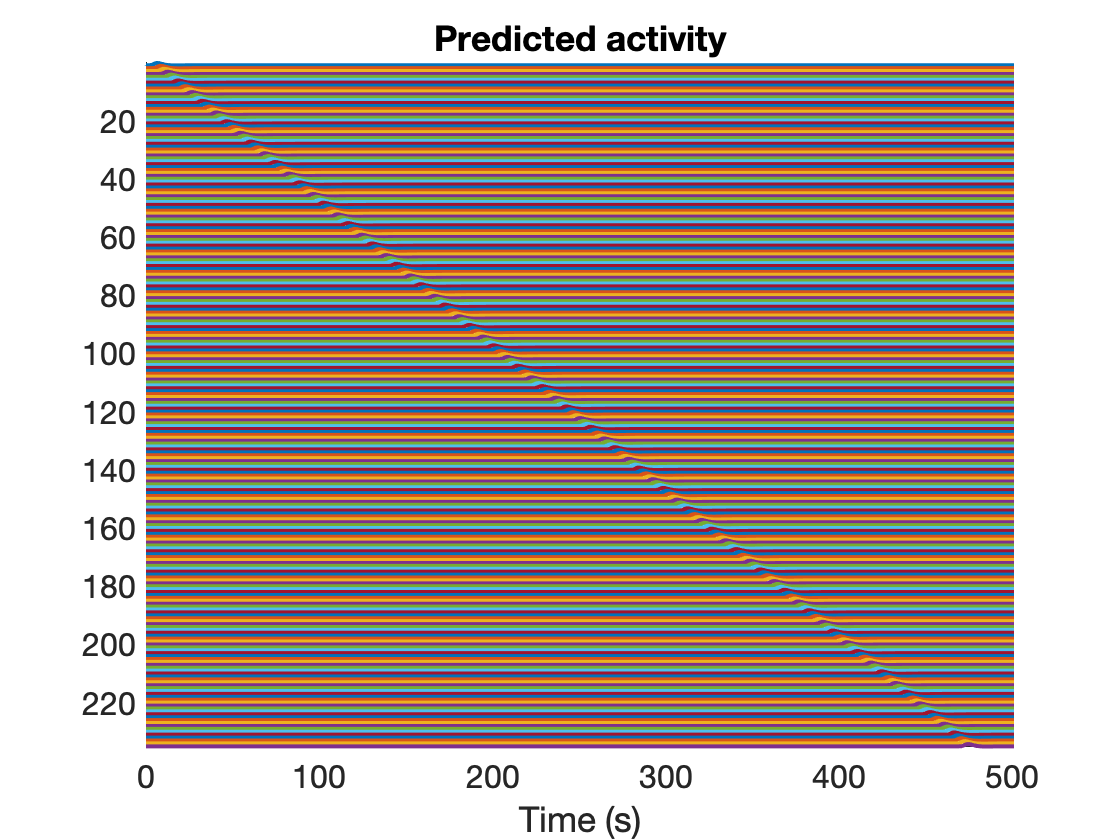

trial_spacing_options = [2:20];
epoch_duration_options = [1 2 3 4];

run_length = 480;
epoch_duration = 1;
TR = 1;

f1 = create_figure('Design matrix');
f2 = create_figure('Efficiency');

for d = 1:length(epoch_duration_options)
    epoch_duration = epoch_duration_options(d);
    
    % Initialize
    eff = zeros(length(trial_spacing_options), 1);
    
    figure(f1)
    
    for i = 1:length(trial_spacing_options)
        
        trial_spacing_in_sec = trial_spacing_options(i);
        
        % Single-trial design onsets
        ons = mat2cell([1:trial_spacing_in_sec:run_length-10]', ones(length([1:trial_spacing_in_sec:run_length-10]), 1))';
        
        clf;
        [X,d,out,handles] = plotDesign(ons, [], TR, 'durs', epoch_duration, 'samefig');
        % drawnow
        
        [eff(i), eff_vector, contrasts] = calcEfficiency(X(1:run_length, :));
        
    end % trial spacing
    
    
    figure(f2)
    plot(trial_spacing_options, eff, '-o', 'LineWidth', 3);
    xlabel('inter-trial spacing (sec)');
    ylabel('Average efficiency per trial');
    
    %drawnow
    
end % epoch duration

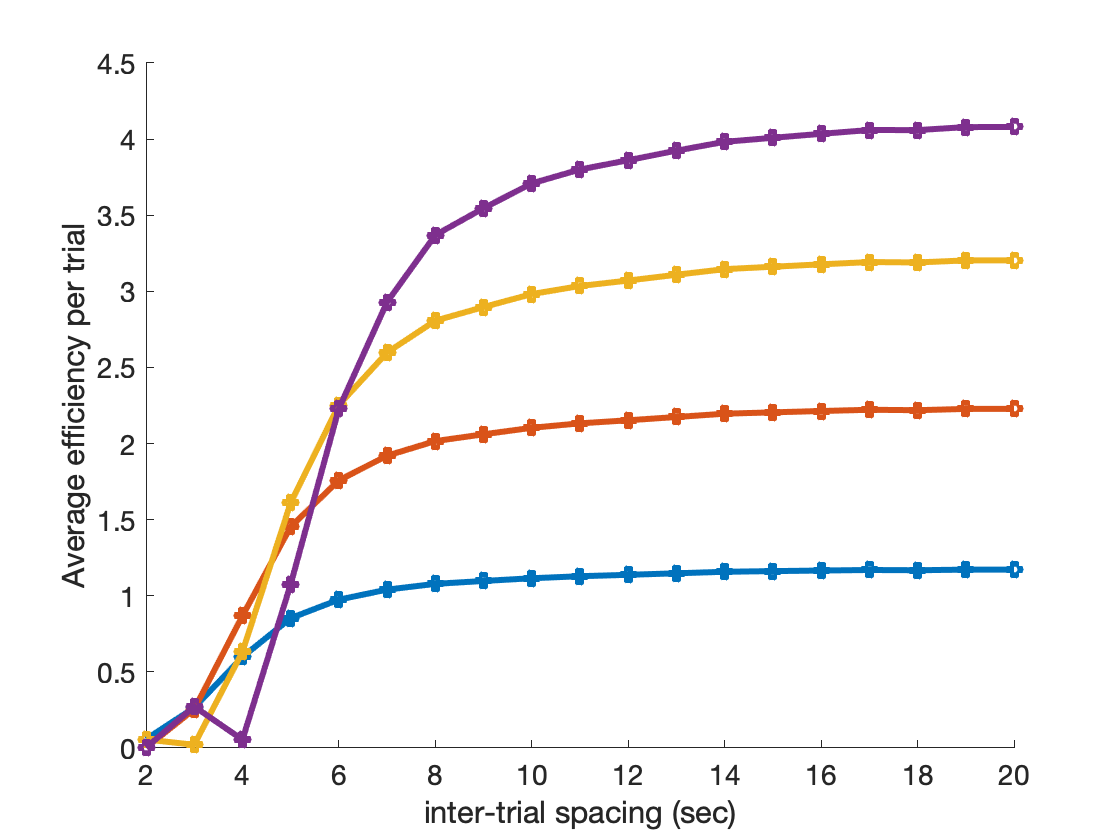

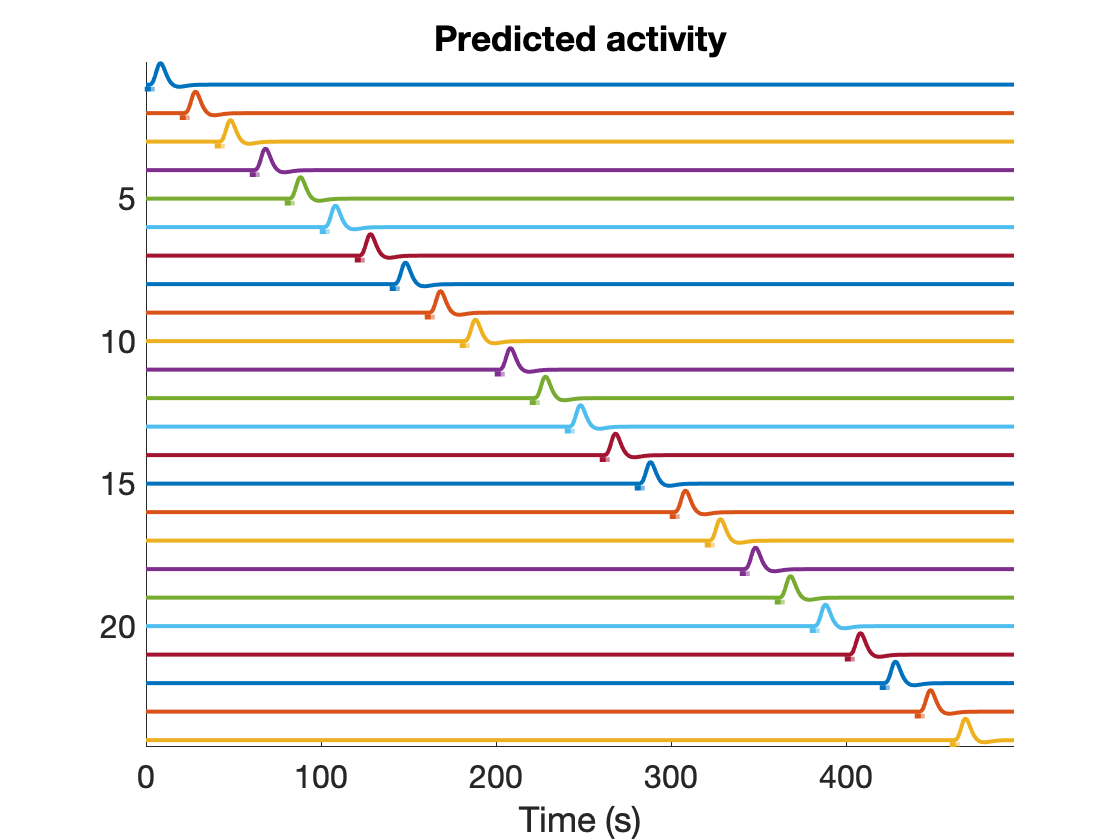


drawnow

## Final model suggestion

Seems like we could show 3 or 4 sec videos for the new task, spaced ~8 sec apart, and would do a pretty reasonable job.

- **Why not longer epochs?**  Longer epochs are more "powerful" but the assumption that you have greater neural activity evenly distributed across the epoch may not be accurate for long epochs especially.  This creates greater potential for mis-modeling, and for **conflation of responses across trials** (see above).

- **Why not longer spacing (e.g. 20 sec)?**  Because we get fewer trials.  Often, we want to analyze responses across single trials as a function of psychological or stimulus conditions. Here, the efficiency (and power) will vary as a function of the square root of the number of trials. This is not built in to the simulation above, which considers only the efficiency for single-trial estimates. (Note: We could do this by generating single trials but then testing efficiency of contrasts across the whole set of trials).

- What we can tell is that with about 8 sec, we don't get much additional benefit from more trial spacing (per trial), and the model is fairly resilient to changes in epoch duration. But we get more trials.  The design below would give us 59 trials in 480 sec (8 min) of scanning.

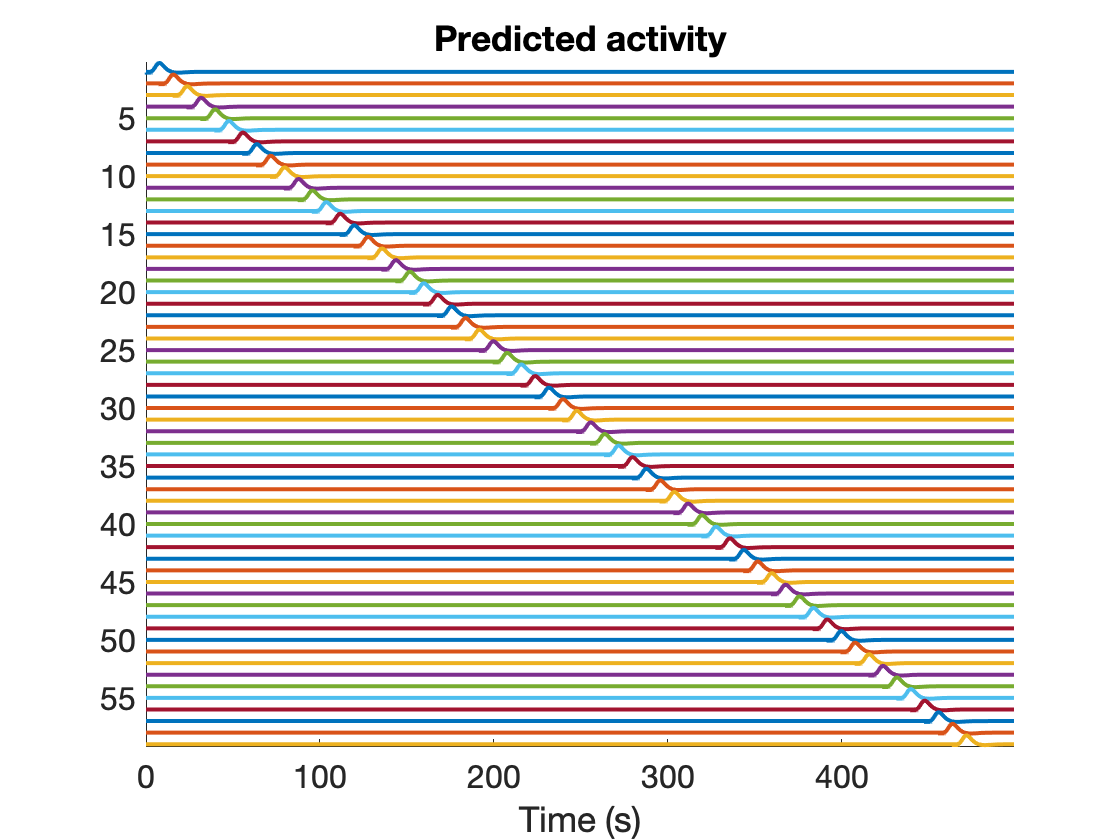

epoch_duration = 3;
trial_spacing_in_sec = 8;

f = findobj('Tag', 'Design matrix');
figure(f);

ons = mat2cell([1:trial_spacing_in_sec:run_length-10]', ones(length([1:trial_spacing_in_sec:run_length-10]), 1))';
[eff_avg, eff_vector] = calcEfficiency(X(1:run_length, :));


clf;
[X,d,out,handles] = plotDesign(ons, [], TR, 'durs', epoch_duration, 'samefig');
drawnow


eff_avg

eff_avg = 4.0798

length(ons)

ans = 59

## Relationship between efficiency, t-values, and power

Efficency should be equal to t-score with true neural cohen's d of 1. 

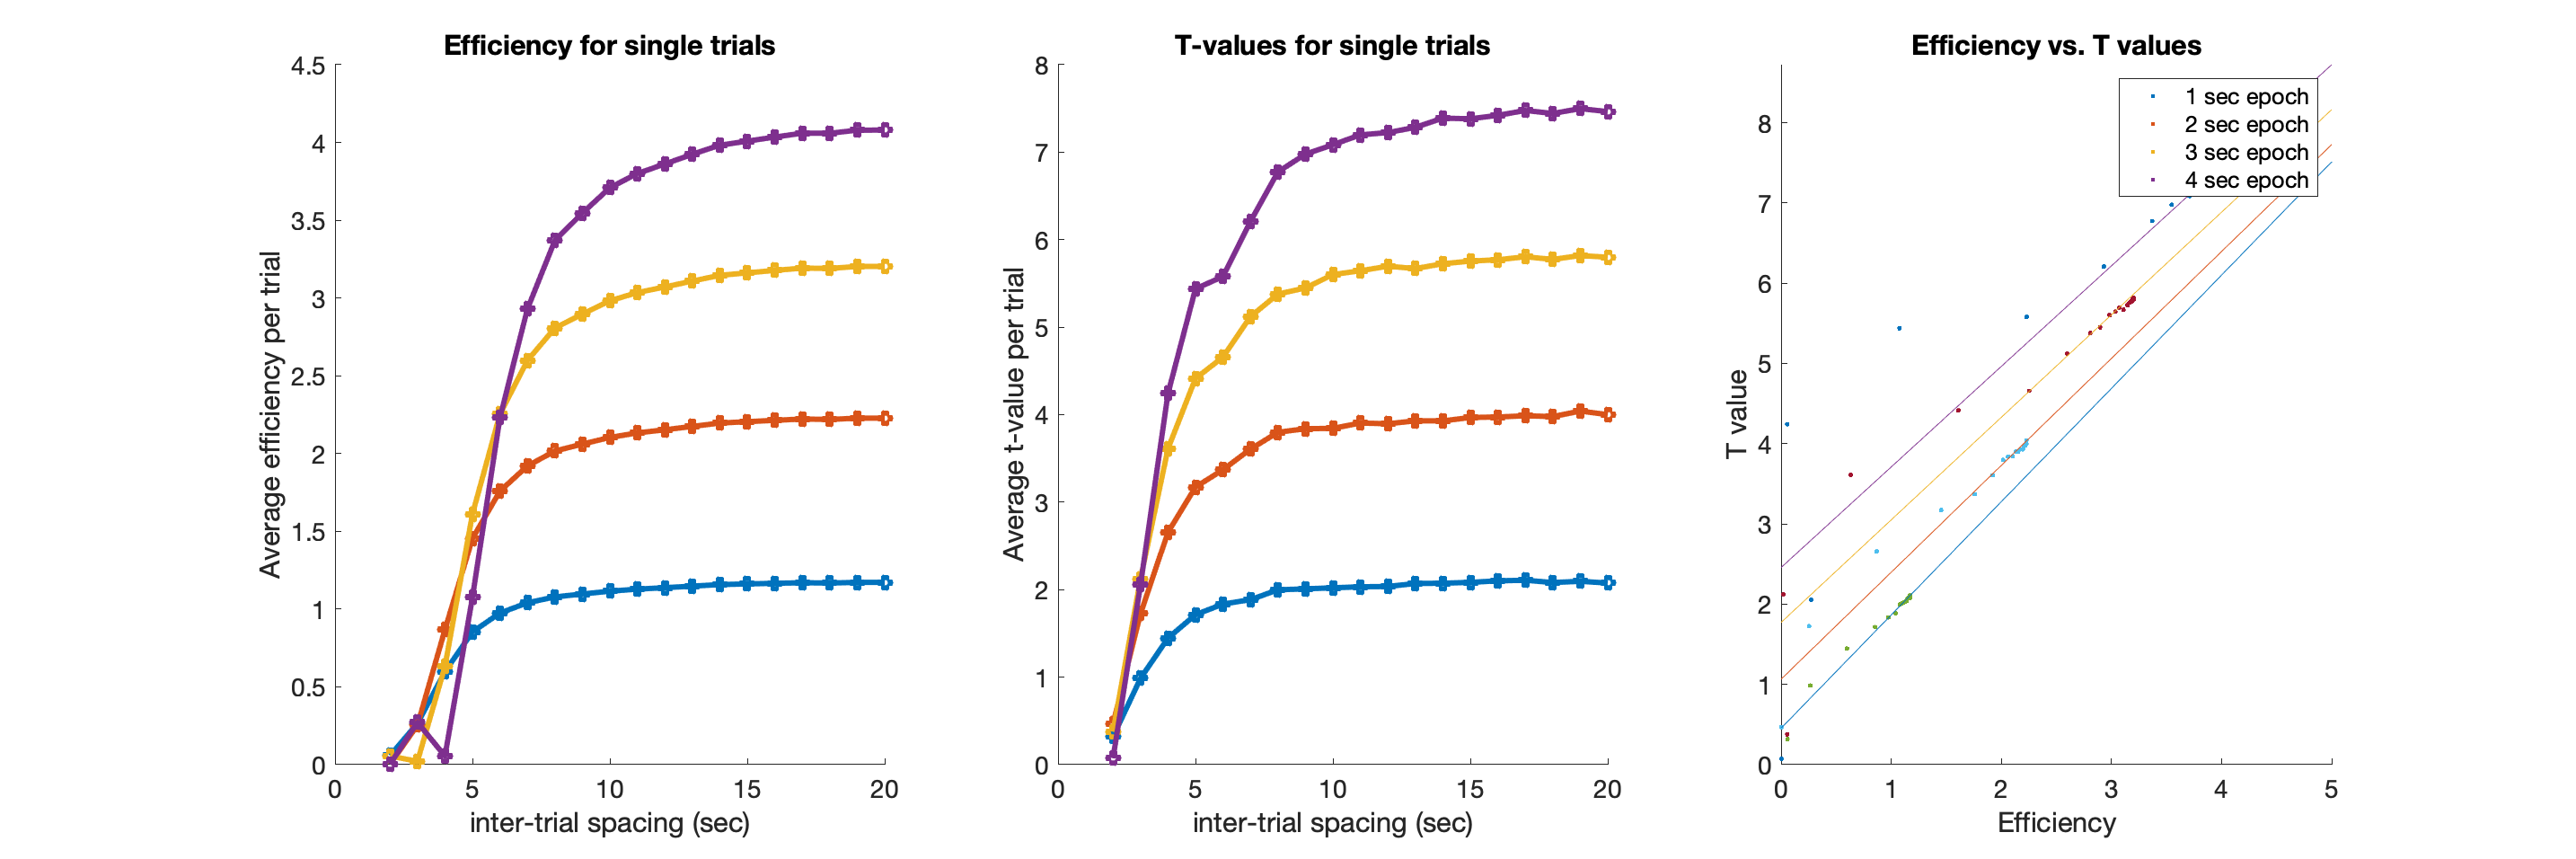

trial_spacing_options = [2:20];
epoch_duration_options = [1 2 3 4];

run_length = 480;
epoch_duration = 1;
TR = 1;

f2 = create_figure('Efficiency, t , power', 1, 3);

% Simulation defaults
niter = 500;
noise_std = 1;

% Initialize vars
ndur = length(epoch_duration_options);
nspace = length(trial_spacing_options);

[t_vals, eff] = deal(cell(1, ndur));


for d = 1:ndur
    
    epoch_duration = epoch_duration_options(d);
    
    % Initialize
    [eff{d}, t_vals{d}] = deal(zeros(nspace, 1));
    
    for i = 1:nspace
        
        trial_spacing_in_sec = trial_spacing_options(i);
        
        [X, eff{d}(i)] = build_design_and_get_efficiency(trial_spacing_in_sec, TR, run_length, epoch_duration);
        
        t_vals{d}(i) = simulate_t_stats(X, noise_std, niter);
          
    end % trial spacing
    
    figure(f2), subplot(1, 3, 1)
    plot(trial_spacing_options, eff{d}, '-o', 'LineWidth', 3);
    xlabel('inter-trial spacing (sec)');
    ylabel('Average efficiency per trial');
    title('Efficiency for single trials')
    
    subplot(1, 3, 2)
    plot(trial_spacing_options, t_vals{d}, '-o', 'LineWidth', 3);
    xlabel('inter-trial spacing (sec)');
    ylabel('Average t-value per trial');
    title('T-values for single trials')
    
    drawnow
    
end % epoch duration

figure(f2), subplot(1, 3, 3)
 
plot([eff{:}], [t_vals{:}], '.'); refline
xlabel('Efficiency')
ylabel('T value')
title('Efficiency vs. T values')
legend({'1 sec epoch' '2 sec epoch' '3 sec epoch' '4 sec epoch'});

drawnow

- There is a linear relationship between efficiency and t-values with roughly a slope of 1, which is expected if efficiency is equivalent to a t-value at a particular reference effect size.  But the t-values are still higher than efficiency, which must be explained. As epoch duration increases, reference effect size goes up because the magnitude of the "true response" (scale of the regressors) goes up, as it should (to some degree). But I'd expect the t-value to = the efficiency with a unit-amplitude response (i.e., 1 sec epoch)...the design matrix is close to this (but a bit above), which might explain it, but not sure. 

- To do: Test relationship with average or contrast across single trials. This should go down for very long trial spacing, creating a non-monotonic efficiency function.

sqrt(n_trials)


## Subfunctions

function [X, eff] = build_design_and_get_efficiency(trial_spacing_in_sec, TR, run_length, epoch_duration)

% Single-trial design onsets
ons = mat2cell([1:trial_spacing_in_sec:run_length-10]', ones(length([1:trial_spacing_in_sec:run_length-10]), 1))';

X = onsets2fmridesign(ons, TR, run_length, [],'durs', epoch_duration);

[eff, eff_vector, contrasts] = calcEfficiency(X(1:run_length, :));

end


function t_val = simulate_t_stats(X, noise_std, niter)

% Simulation of t-stats with Gaussian noise
true_y = sum(X, 2);
sz = size(true_y);

t_val = NaN .* zeros(niter, 1);

for j = 1:niter
    
    y = true_y + noise_std .* randn(sz);
    
    [b dev stats] = glmfit(X, y, 'normal', 'Constant', 'off'); % we have already added a constant manually
    
    t_val(j, 1) = mean(stats.t(1:end-1)); % average t excluding intercept
    
end

% Average over iterations
t_val = mean(t_val);

end